n = 1

n = 1

syms x
N = sym(0:n+1);
Phi = legendreP(N,x).*sqrt((2.*N+1)./2)

$$Phi = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{3}\,x}{2} & \frac{\sqrt{2}\,\sqrt{5}\,\left(\frac{3\,x^{2}}{2}-\frac{1}{2}\right)}{2} \end{array}\right)$$

divPhi = diff(Phi)

$$divPhi = \left(\begin{array}{ccc} 0 & \frac{\sqrt{2}\,\sqrt{3}}{2} & \frac{3\,\sqrt{2}\,\sqrt{5}\,x}{2} \end{array}\right)$$

X = solve(Phi(end)==0)

$$X = \left(\begin{array}{c} -\frac{\sqrt{3}}{3}\\ \frac{\sqrt{3}}{3} \end{array}\right)$$

% W = int(Phi(end)./(x-X),x,[-1,1])./subs(div_Phi(end),x,X)
W = 2./(1-X.^2)./subs(divPhi(end).^2,x,X).*(2.*n+3)./2

$$W = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

% W = simplify(W)
double(W)

ans =      1
     1


sum_P = sum(W.*subs(Phi(1:n+1).^2,x,X),'all')/(n+1);
double(sum_P)

ans = 1

f = @(x)exp(x)

f = 包含以下值的 function_handle :
    @(x)exp(x)


PhiX = simplify(subs(Phi(1:end-1),x,X));
simplify(PhiX*PhiX');
B = f(X);
CHat = double(PhiX\B)

CHat =     1.6565
    0.8626


double(PhiX'*(B.*double(W))-CHat)

ans = 1.0e-16 *

   -0.1646
   -0.0615


t=0

t = 0

Err_all = Err

Err_all =     1.2302
    0.5744
    0.0000


clf
C = rand(n+1,1)*2-1;
X = double(X);
PhiX = double(PhiX);
CHat = double(CHat);
Err = ones(n+2,1);
Err(1) = norm(C-CHat).^2;
for k = 1:n+1
    C = C + (f(X(k))-C'*PhiX(k,:)')/norm(PhiX(k,:))^2*PhiX(k,:)';
    Err(k+1) = norm(C-CHat);
    f(X(k))-C'*PhiX(k,:)'% eliminate one directional components at a time.
end

ans = -1.1102e-16

ans = -4.4409e-16

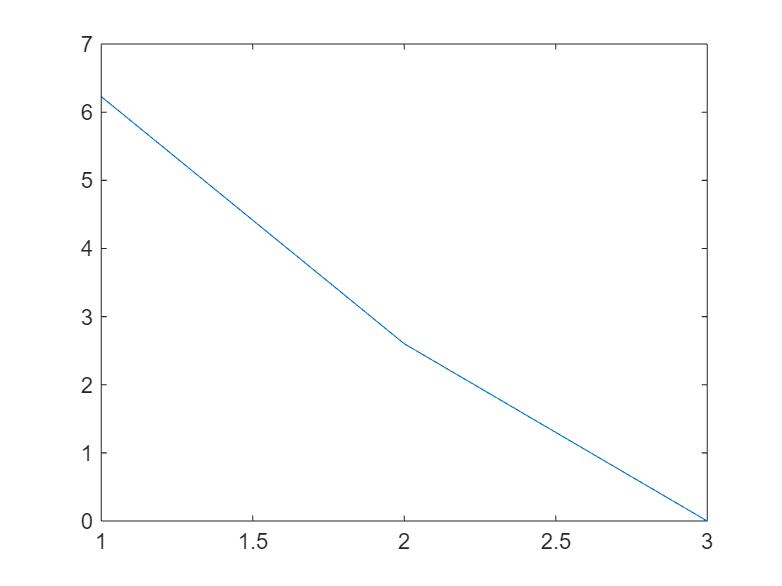

% semilogy(Err)
% plot(Err(1:end))
Err_all = Err_all+Err;
t = t+1;
plot(Err_all/t)

Only converges to zero on final step